%画三维曲线
% subplot(1,3,1);
t=0:0.01:15;
x=sin(t); y=cos(t); z=t;
plot3(x,y,z,'-.')
view(-60,18)    %选择视角

% subplot(1,3,2);
sphere(40) %画旋转提图形(用三个21*21的矩阵组成的三维单位球)

%画空间曲面三步骤
% subplot(1,3,3);
[X,Y]=meshgrid(-8:0.5:8);%创建数据网格
R=sqrt(X.^2+Y.^2)+eps;%构建函数(eps为一个非常小的量,防止取0时候出现无穷大)
Z=sin(R)./R;
surf(X,Y,Z); %画表面图

figure
subplot(2,2,1)
mesh(X,Y,Z)    %网线图
subplot(2,2,2)
meshz(X,Y,Z)   %网线图加基准平面
subplot(2,2,3)
surfc(X,Y,Z)   %表面图加等高线
subplot(2,2,4)
meshc(X,Y,Z)   %网线图再加等高线

两面交线

[x,y]=meshgrid(-2:0.01:2);
z1=x.^2-2*y.^2;
z2=2*x-3*y;
mesh(x,y,z1);
hold on;
mesh(x,y,z2);
r0=abs(z1-z2)<0.01 %满足此条件的地方置1，其余置0
xx=x(r0~=0)
yy=y(r0~=0)
zz=z1(r0~=0)
plot3(xx,yy,zz,'k*')

画四面体并填充颜色

A=[0,0,0];  B=[1,0,0];
C=[0.5,0.5,0.5]; D=[0.5,0.5,0];
X=[A(1),B(1),A(1);    %X坐标
   B(1),C(1),C(1);
   C(1),D(1),D(1);
   A(1),B(1),A(1)];
Y=[A(2),B(2),A(2);
   B(2),C(2),C(2);
   C(2),D(2),D(2)
   A(2),B(2),A(2)];
Z=[A(3),B(3),A(3);
   B(3),C(3),C(3); 
   C(3),D(3),D(3);
   A(3),B(3),A(3)];
plot3(X,Y,Z)
view(-179,-42);
figure %给三个三角形填色
hold on;
fill3(X(:,1),Y(:,1),Z(:,1),'g');
fill3(X(:,2),Y(:,2),Z(:,2),'r');
fill3(X(:,3),Y(:,3),Z(:,3),'y');
view(-179,-42);

四面体画法2

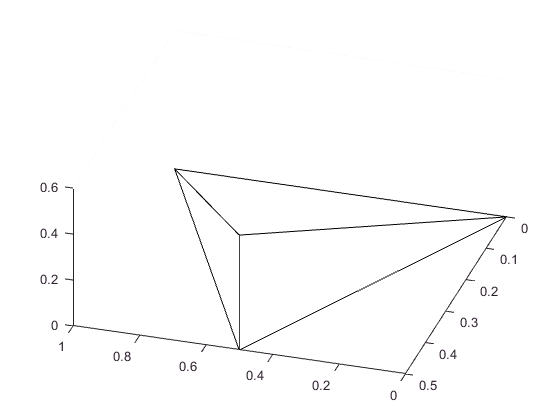

xyz=[0,0,0;1,0,0;0.5,0.5,0.5;0.5,0.5,0]; %顶点坐标
fac=[1,2,3;2,3,4;1,3,4]; %组成一个表面的顶点
patch('vertices',xyz,'faces',fac,'facecolor','w');
view(-163,50)

柱体例子

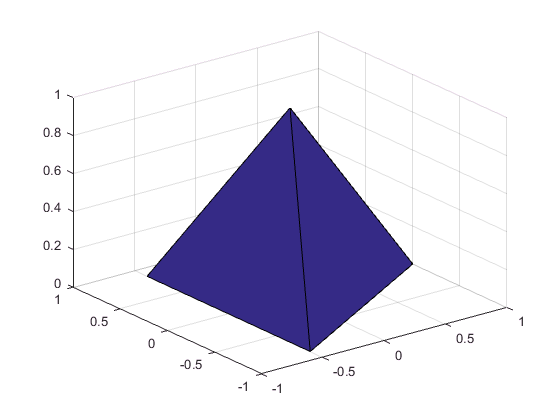

cylinder([1,0],3); %第一个参数代表着柱体在竖直方向等间距处的半径

                   %参数3代表母线3条

figure
x=0:0.1:3.5;
y=sin(x)

y =          0    0.0998    0.1987    0.2955    0.3894    0.4794    0.5646    0.6442    0.7174    0.7833    0.8415    0.8912    0.9320    0.9636    0.9854    0.9975    0.9996    0.9917    0.9738    0.9463    0.9093    0.8632    0.8085    0.7457    0.6755    0.5985    0.5155    0.4274    0.3350    0.2392    0.1411    0.0416   -0.0584   -0.1577   -0.2555   -0.3508


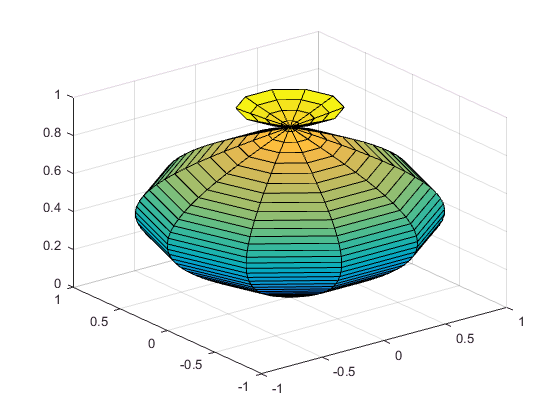

cylinder(y,10);